clear
clc
close all

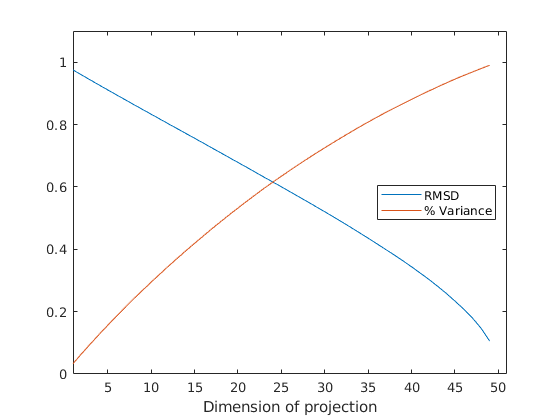

%Generate the dataset
dataset = randn(50,500);

%Calculate the mean
mean_vector = mean(dataset,2);

%Zero mean the dataset by subtracting the mean
zero_dataset = dataset - mean_vector;

%Calculate the covariance matrix for the zero dataset
covariance = cov(zero_dataset');
    
%Compute variance for each dimension
values = eig(covariance);
sum_total_values = sum(values);

%Initialise errors and eigenvalue-percentages arrays
errors = zeros(1,49);
var_subs = zeros(1, 49);

for q=1:49
    
    %Compute the reduced eigenvalues and eigenvactors of the covariance matrix
    [E, reduced_values] = eigs(covariance, q);
    sum_reduced_values = sum(diag(reduced_values));
    
    %Compute the percentage of variance captured by subspace
    var_sub = sum_reduced_values/sum_total_values;
    var_subs(1,q) = var_sub;
    
    %Compute transpose of reduced eigenvectors
    E_T = E';
    
    %Reduce the dataset by multipling with E_T
    reduced_dataset = E_T*dataset;
    
    %Generate new dataset from reduced dataset
    new_dataset_zerod = E*reduced_dataset;
    new_dataset = new_dataset_zerod + mean_vector;
    
    %Estimate the error
    RMSD = (sqrt(mean(mean((dataset-new_dataset).^2))));
    
    errors(1,q) = RMSD;
end

%Plotting RMSD for different q-values
plot(errors);
hold on;
plot(var_subs);
xlabel('Dimension of projection')
xlim([1 51]);
ylim([0 1.1]);
legend({'RMSD','% Variance'},'Location','east')
hold off;

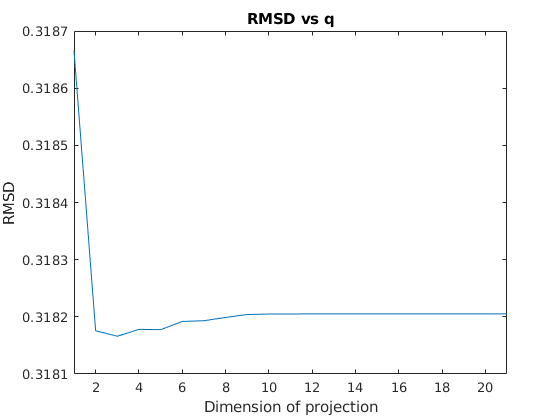

load choles_all

%Generate the dataset
dataset = p;

%Calculate the mean
mean_vector = mean(dataset,2);

%Zero mean the dataset by subtracting the mean
zero_dataset = dataset - mean_vector;

%Calculate the covariance matrix for the zero dataset
covariance = cov(zero_dataset');
    
%Compute variance for each dimension
values = eig(covariance);
sum_total_values = sum(values);

%Initialise errors and eigenvalue-percentages arrays
errors = zeros(1,21);
var_subs = zeros(1, 21);

for q=1:21
    
    %Compute the reduced eigenvalues and eigenvactors of the covariance matrix
    [E, reduced_values] = eigs(covariance, q);
    sum_reduced_values = sum(diag(reduced_values));
    
    %Compute the percentage of variance captured by subspace
    var_sub = sum_reduced_values/sum_total_values;
    var_subs(1,q) = var_sub;
    
    %Compute transpose of reduced eigenvectors
    E_T = E';
    
    %Reduce the dataset by multipling with E_T
    reduced_dataset = E_T*dataset;
    
    %Generate new dataset from reduced dataset
    new_dataset_zerod = E*reduced_dataset;
    new_dataset = new_dataset_zerod + mean_vector;
    
    %Estimate the error
    RMSD = (sqrt(mean(mean((dataset-new_dataset).^2))));
    
    errors(1,q) = RMSD;
end

%Plotting RMSD for different q-values
plot(errors);
xlim([1 21]);
title("RMSD vs q")
xlabel('Dimension of projection')
ylabel('RMSD')

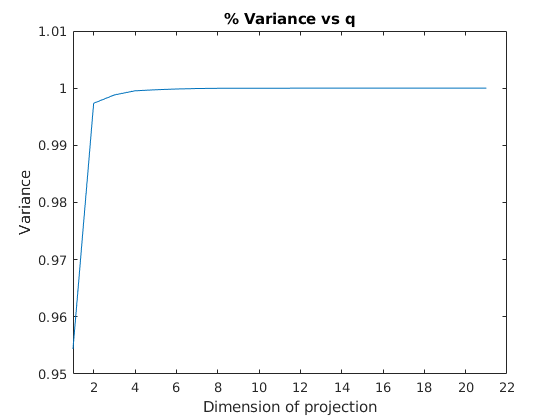


%Plotting percentage variance for different q-values
plot(var_subs);
title("% Variance vs q")
xlabel('Dimension of projection')
ylabel('Variance')
xlim([1 22]);
ylim([0.95 1.01]);